# **Script for miniEPSC analysis**

Oct 2021, Man Ho Wong (m.wong@pitt.edu)

# Running for the first time

Start from section 1

# Continuing last session

See [section 1.5](about:blank<#H_FA8C9712>)

# ----------------------------------------------------

# 1. Set up the environment

### 1.1 Requirements

- This script was tested in MATLAB **R2021b **on Windows 10. Earlier versions supporting the data type `table` should also work.

- This script and the associated files (all stored in the folder '**analyzeMini**')

- **Statistics and Machine Learning Toolbox** (To add, go to 'Add-Ons' > 'Get Add-Ons'; free to download with Pitt account)

- Raw data and folders organized in the format and directory structure specified below.

..........................................................................................................

### 1.2 Data format

- Save miniEPSC events of each of your recordings as a `.txt` file.

- Save your recording information in `recordingInfo.xlsx`**.**

- Save the above files in one folder, and name it '`rawData`'.

add examples... templates...

..........................................................................................................

### 1.3 Add folder paths

To run this live scipt, you need to :

- Add the path of the script folder '`analyzeMini`' to MATLAB search path.

- Set the current folder to the folder (refered as the 'project folder' below) containing '`rawData`'.

Please enter *full* folder path below:

scriptFolder = "C:\Users\manho\OneDrive - University of Pittsburgh\M and M\MATLAB scripts\manhoscripts\analyzeMini";
projFolder = "C:\Users\manho\OneDrive - University of Pittsburgh\data\ELS project\ephys\MATLAB analysis\all" ;

addpath(scriptFolder);
path = genpath(scriptFolder);
addpath(path); % add all subfolders in scriptFolder to path

cd(projFolder);
path = genpath(projFolder);
addpath(path); % add all subfolders in projFolder to path

fprintf('Done! Folder paths were added.');

Done! Folder paths were added.

**Note**: Remember to reset the paths if you have moved the folders.

After this, you can [start a new analysis session](about:blank<#H_A41AA0F1>) or [load a previous session](about:blank<#H_FA8C9712>).

..........................................................................................................

### 1.4 Start a new analysis session

This script creates a folder named '`analysis`' in your data folder. Processed data and results of analysis are stored in this folder.

Start a new analysis session by clicking the button below:

- the folder '`analysis`' will be created

- the current `Workspace` will be cleaned (save it if you need to)

- default values will be loaded

 

if ~exist('projFolder','var') || ~exist('scriptFolder','var')
    fprintf('Please go back and add the required folder paths!\n')
    return
end



% Clear workspace
quest = {['Workspace will be cleared before starting a new analysis session. ' ...
    'Please save your Workspace if you still need it.'], ...
    'Continue to start a new session?'};
response = questdlg(quest,'Starting a new analysis session','Yes','No','No');

switch response
    case {'Yes'}
        clearvars -except scriptFolder projFolder
    case {'No',''}
        return
end


load(scriptFolder+'/defaultValues.mat');
mkdir ('analysis');

save('analysis/workspace.mat');
path = genpath(projFolder);
addpath(path); % add all subfolders in dataFolder to path

..........................................................................................................

### 1.5 Load previous analysis session

To resume a previous analysis session, reuse the `Workspace` variables and processed data, or switch between different sessions, add folder paths in [step 1.3](about:blank<#H_77BA0668>) first and click the button below.

 

if ~exist('projFolder','var') || ~exist('scriptFolder','var')
    fprintf('Please add the required folder paths in the previous step first.\n')
    return
end

% Clear workspace
quest = {['Workspace will be cleared before loading a previous analysis session. ' ...
    'Please save your Workspace if you still need it.'], ...
    'Continue to load the session?'};
response = questdlg(quest,'Load previous analysis session','Yes','No','No');
switch response
    case {'Yes'}            
        clearvars -except scriptFolder projFolder
    case {'No',''}
        return
end

cd(projFolder);

% store projFolder and scriptFolder temporally as tempProjectFolder
% and tempScriptFolder as they will be replaced by those in
% workspace.mat once the file is loaded
tempProjFolder = projFolder;     
tempScriptFolder = scriptFolder;

% load workspace
fprintf('Loading ''workspace.mat''...\n');

Loading 'workspace.mat'...


load('analysis/workspace.mat');

% update these two variables with new values
projFolder = tempProjFolder;
scriptFolder = tempScriptFolder;
clearvars tempProjFolder tempScriptFolder % no longer needed

% load defultValues, summary, groupedData, compiledData
fprintf('Loading ''defaultValues.mat''...\n');

Loading 'defaultValues.mat'...


load(scriptFolder+'/defaultValues.mat');
if exist('analysis/summary.mat',"file")
    fprintf('Loading ''summary.mat''...\n');
    load('analysis/summary.mat');
end

Loading 'summary.mat'...


if exist('analysis/groupedData.mat',"file")
    fprintf('Loading ''groupedData.mat''...\n');
    load('analysis/groupedData.mat');
end

Loading 'groupedData.mat'...


if exist('analysis/compiledData.mat',"file")
    fprintf('Loading ''compiledData.mat''...\n');
    load('analysis/compiledData.mat');
end

Loading 'compiledData.mat'...



% add all subfolders in projFolder to path
path = genpath(projFolder);
addpath(path);

fprintf('Previous session loaded.\n');

Previous session loaded.


`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# 2. Import raw data

The following function:

- extracts mEPSC event data from each `.txt` file in your data folder

- organizes the data according to the info provided by the Excel file '`recordingInfo.xlsx`'

- sorts the mEPSC events by time

- calculate the inter-event interval (iei) for each event

- compiles all recordings into one single data set

- store the data set in a MATLAB `table` named '`compiledData`'

For each anaylsis session, you only need to import your raw data once, unless you have made changes to your data set (e.g. new recordings are added). 

 

% Check if recordingInfo.xlsx exists.
if ~exist('rawData/recordingInfo.xlsx','file')
    fprintf('The required file ''recordingInfo.xlsx'' does not exist in the folder rawData!\nMake sure you have set the correct current folder.\n');
    return
end

% If compiledData already exists, ask user if they want to compile again.
if exist('analysis/compiledData.mat', 'file')
    quest = {['This action will replace the previously compiled data in your project folder.' ...
        'You may need to compute the data points again (if you have done so). '], ...
        'Do you want to continue?'};
    response = questdlg(quest,'Compile again?','Yes','No','No');
    switch response
        case {'Yes'}
            compiledData = importRecordings('rawData/recordingInfo.xlsx');
        case {'No',''}
            fprintf('No change is made.');
            return
    end
    else
        compiledData = importRecordings('rawData/recordingInfo.xlsx');
end

Compiling data. Please wait...


Saving data. Please wait...
Done! Compiled data was saved as 
'compiledData.mat' in the folder 'analysis'.


`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# 3. Compute data points

1. Data points (n) need to be computed before analysis. This function generates one data point for each recording, where each data point represents the arithmetic mean of each of the variables (e.g. amplitude, iei, etc.) of the events. The computed data points can be found in the `table` '`compiledData`' in Workspace.

 

% Load default values.
statistic  = 'mean';
load(scriptFolder+'/defaultValues.mat','varList');

% Check if compiledData is loaded.
if ~exist('compiledData','var')
    quest = {'compiledData is not found in the Workspace.', ...
        'Do you want to load it into the Workspace now?'};
    response = questdlg(quest,'Load compiledData?','Yes','No','No');
    switch response
        case {'Yes'}
            [file,path] = uigetfile('*.mat','Select a file','analysis');
            if isequal(file,0)  % If user did not choose a file
                fprintf('No change is made.');
                return
            elseif file ~= "compiledData.mat"
                fprintf('This is not ''compiledData.mat''.');
                return                
            else
                fprintf('Loading compiledData...\n');
                load(fullfile(path,file),'compiledData');
                compiledData = computeDataPoint(compiledData,varList,statistic);                
            end
        case {'No',''}
            fprintf('No change is made.');
            return
    end
else
    compiledData = computeDataPoint(compiledData,varList,statistic);
end

Computing data points............Done!
Data points were stored in the column 'dataPoints' in 'compiledData'.
***
Remember to save compiledData in the next step before you close MATLAB.


% Create a list of statistics computed. This list is needed for dropdown controls in later sections.
statisticDone = compiledData.dataPoints{1}.Properties.VariableNames;


2. Optional: You can add another type of statistic to compute the data points:

- arithmetic mean (`mean)` (default)

- median ----> select `median`

- standard deviation ----> select `sd`

- coefficient of variance ----> select `cv`

- standard error of mean ----> select `sem`

statistic  = statisticList(5) 

statistic = "sem"


% Load default values.
load(scriptFolder+'/defaultValues.mat','varList');

% Check if compiledData is loaded.
if ~exist('compiledData','var')
    quest = {'compiledData is not found in the Workspace.', ...
        'Do you want to load it into the Workspace now?'};
    response = questdlg(quest,'Load compiledData?','Yes','No','No');
    switch response
        % If user chooses to load compiledData
        case {'Yes'}
            [file,path] = uigetfile('*.mat','Select a file','analysis');
            if isequal(file,0)
                fprintf('No change is made.');
                return
            elseif file ~= "compiledData.mat"
                fprintf('This is not ''compiledData.mat''.');
                return                
            else
                fprintf('Loading compiledData...\n');
                load(fullfile(path,file),'compiledData');
                compiledData = computeDataPoint(compiledData,varList,statistic);                
            end
        % If user chooses not to load compiledData
        case {'No',''}
            fprintf('No change is made.');
            return
    end
else
    % If compiledData exists, append new data points to it.
    compiledData = computeDataPoint(compiledData,varList,statistic);
end

Computing data points............Done!
Data points were stored in the column 'dataPoints' in 'compiledData'.
***
Remember to save compiledData in the next step before you close MATLAB.


3. When you are done with the above steps, remember to save '`compiledData`':

 
fprintf('Saving data. Please wait...');

Saving data. Please wait...

save('analysis/compiledData.mat','compiledData');
fprintf('Done! ''compiledData'' was saved as ''compiledData.mat'' in the folder ''analysis''.\n');

Done! 'compiledData' was saved as 'compiledData.mat' in the folder 'analysis'.


`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# 4. Define experiment groups

1. Set filter criteria to select recordings:

filterValue = struct;
filterValue.minAge = 53;  % Minimum age
filterValue.maxAge = 999; 
% Maximum age                    

% Listbox
factor = ["researcher" "condition" "facility" "sex" "cellType" "genotype" "treatment"];
nFactor = length(factor);
if ~exist('lastSelection','var')
    lastSelection = cell(nFactor,1);  % lastSelection stores user's last selected items
end
for iFactor = 1:nFactor
    list = categories(compiledData.(factor(iFactor)));
    [index,tf] = listdlg('PromptString',{'Select '+factor(iFactor)+'(s)',...
        'Press and hold ''Ctrl'' key to select multiple groups.',''},...
        'ListSize',[250,300],'ListString',list,'OKString','Next',...
        'InitialValue',lastSelection{iFactor,1});
    filterValue.(factor(iFactor)) = list(index);
    lastSelection{iFactor,1} = index;   % save user's selections 
    if tf == 0,fprintf('Filter not set!\n');return;end
end
fprintf('The filter is set!\n');

The filter is set!


disp('Click here to change filter values manually.');

Click here to change filter values.


2. Name this group:

newGroup = "lbnPittM53gfpP" ;

% Check if groupedData is loaded.
if ~exist('groupedData','var')
    quest = {'groupedData is not found in the Workspace.', ...
        'You can create a new table for groupedData or load it from previous session.'};
    response = questdlg(quest,'Load groupedData?','Load groupedData','Create new table','Create new table');
    switch response
        % If user chooses to load groupedData
        case {'Load groupedData'}
            [file,path] = uigetfile('*.mat','Select a file','analysis');
            if isequal(file,0)
                fprintf('No change is made.');
                return
            elseif file ~= "groupedData.mat"
                fprintf('This is not ''groupedData.mat''.');
                return                
            else
                fprintf('Loading groupedData...\n');
                load(fullfile(path,file),'groupedData');
                groupedData = groupRecordings(compiledData,groupedData,filterValue,newGroup,varListInclFreq);                
            end
        % If user chooses not to load groupedData
        case {'Create new table'}
            groupedData = table;
            groupedData = groupRecordings(compiledData,groupedData,filterValue,newGroup,varListInclFreq);
    end
else
    % If groupedData exists, append new group to it.
    groupedData = groupRecordings(compiledData,groupedData,filterValue,newGroup,varListInclFreq);
end

Grouping recordings. Please wait.............Done!
'lbnPittM53gfpP' was added to 'groupedData' in Workspace.

********* Reminder *********
- If you have computed new data points, you will need to
group the data again to include those points.
- Remember to save groupedData in the next step before you close MATLAB.


Grouped recordings can be found in the table '`groupedData`' in Workspace.

3. Repeat step 1 to 2 to create more groups. When you are done, remember to save '`groupedData`':

 
fprintf('Saving data. Please wait...');

Saving data. Please wait...

save('analysis/groupedData.mat','groupedData');
fprintf('Done! ''groupedData'' was saved as ''groupedData.mat'' in the folder ''analysis''.\n');

Done! 'groupedData' was saved as 'groupedData.mat' in the folder 'analysis'.


Optional: Combine multiple groups into one group.

pooledGroup = "lbnF53tdtP" ;
inputGroups = selectGroups(groupedData,0);
groupedData = poolGroups(groupedData,inputGroups,pooledGroup);

Combining groups. Please wait...Done!
'lbnF53tdtP' was added to 'groupedData' in Workspace.

*********
Remember to save groupedData before you close MATLAB.


`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# 5. Quick analysis

**After** you have defined the experiment groups, you can perform the following steps.

..........................................................................................................

### 5.1 Summary statistics

This function generates a summary describing the *data points* of each group. Statistics included:

- n number (i.e. number of data points)

- mean

- minimum and maximum values

- median

- standard deviation

- coefficient of variance

- standard error of mean

Indicate the type of data points you want to analyze:

statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);
pointStat  = statisticDone(1);
variable   = varListInclFreq(2); 

% Create a list of statistics computed.
statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);

% Check if user inputs are valid
if ~exist('groupedData','var'),fprintf('''groupedData'' not found!');return, end
if ismember('dataPoints',groupedData.Properties.VariableNames)
    if ~ismember(pointStat,statisticDone)
        fprintf('Data points for the selected statistic have not been computed yet!\n');return
    end
else 
    fprintf('Data points have not been computed yet!\n');return
end
if ~exist('summary','var')
    summary = table;
end
summary.(variable){pointStat} = summarize(groupedData,pointStat,variable);

Error using summarize (line 22)
Unrecognized table variable name 'dataPoints'.

save('analysis/summary.mat','summary');
fprintf('Results were saved as ''summary.mat'' in the folder ''analysis''.\n');
summary.(variable){pointStat}

..........................................................................................................

### 5.2 t test and rank sum test

1. Indicate the data point type and select TWO groups:

statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);
statistic  = statisticDone(1);
variable   = varListInclFreq(2); 

% Check if user inputs are valid
if ~exist('groupedData','var'),fprintf('''groupedData'' not found!');return, end
if ismember('dataPoints',groupedData.Properties.VariableNames)
    if ~ismember(statistic,statisticDone)
        fprintf('Data points for the selected statistic have not been computed yet!\n');return
    end
else 
    fprintf('Data points have not been computed yet!\n');return
end

% Ask user to select two groups
selectedGroup = selectGroups(groupedData,2)

selectedGroup = 2×1 cell array
    {'ctrlPittF53gfpP'}
    {'lbnPittF53gfpP' }


2. Select a test to run:

test = "ttest2" 

test = "ttest2"

% Extract data points and run statistic test

input1 = groupedData.dataPoints{selectedGroup{1}}.(variable){statistic}.dataPoints;
input2 = groupedData.dataPoints{selectedGroup{2}}.(variable){statistic}.dataPoints;
switch test
    case 'ttest',   [p,h,ci,stats] = ttest(input1,input2)
    case 'ttest2',  [h,p,ci,stats] = ttest2(input1,input2)
    case 'ranksum', [p,h,stats] = ranksum(input1,input2)
end

h = 0

p = 0.9394

ci =    -1.9119
    1.7755


stats = struct with fields:
    tstat: -0.0769
       df: 21
       sd: 2.1239


..........................................................................................................

### 5.3 ANOVA and multiple comparison

1. Indicate the data point type and select group(s):

statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);
statistic  = statisticList(1);
variable   = varListInclFreq(1); 

% Check if user inputs are valid
if ~exist('groupedData','var'),fprintf('''groupedData'' not found!');return, end
if ismember('dataPoints',groupedData.Properties.VariableNames)
    if ~ismember(statistic,statisticDone)
        fprintf('Data points for the selected statistic have not been computed yet!\n');return
    end
else 
    fprintf('Data points have not been computed yet!\n');return
end

% Ask user to select groups
selectedGroup = selectGroups(groupedData,0)

selectedGroup = 8×1 cell array
    {'ctrlF53'        }
    {'lbnF53'         }
    {'ctrlF53tdtP'    }
    {'lbnF53tdtP'     }
    {'ctrlPittF53tdtP'}
    {'ctrlPittF53gfpP'}
    {'lbnPittF53tdtP' }
    {'lbnPittF53gfpP' }


nGroup = length(selectedGroup);

2. Indicate factor(s) to analysis (for ANOVA):

- Default factor, 'group': recordings will be analyzed as how they were grouped.

- Other factors: recordings will be analyzed as groups defined by the selected factor(s), **regardless how they were grouped previously**.

- To analyze recordings by individual animals, select 'mouseID'.

 

% Generate a list of factors
factorList = string(groupedData.Properties.VariableNames);
% Remove these elements from the list
factorList(factorList=="dataPoints" | factorList=="events" | factorList=="minAge" | factorList=="maxAge") = [];    
% Add group, age group and mouseID to the list
factorList = ["group",factorList,"ageGroup","mouseID"];

% Ask user to select factor(s)
[index,tf] = listdlg('PromptString',...
    {'Select factor(s) to run ANOVA.', ...
    '*Select ''group'' to run ANOVA just as how recordings were grouped. (Default)','' ...
    'Press and hold ''Ctrl'' key to select multiple factors.',''},...
    'ListSize',[250,300],'ListString',factorList,'InitialValue',1);
selectedFactor = factorList(index)

selectedFactor = "group"

3. Select a test to run. *If nested ANOVA is selected, please also define the nesting relationship (see [note](about:blank<#M_FD4A813B>)).

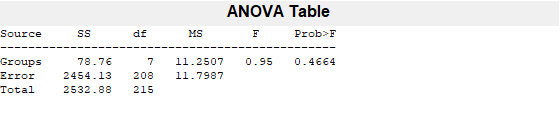

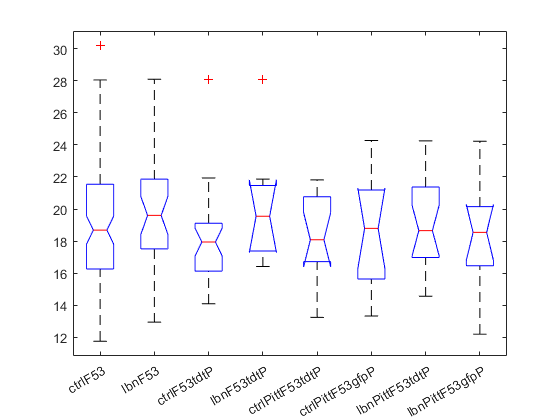

P = 0.4664

T = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[   78.7550]}    {[  7]}    {[ 11.2507]}    {[  0.9536]}    {[  0.4664]}
    {'Error' }    {[2.4541e+03]}    {[208]}    {[ 11.7987]}    {0×0 double}    {0×0 double}
    {'Total' }    {[2.5329e+03]}    {[215]}    {0×0 double}    {0×0 double}    {0×0 double}


STATS = struct with fields:
    gnames: {8×1 cell}
         n: [90 33 29 8 14 12 19 11]
    source: 'anova1'
     means: [19.0326 20.0048 18.1910 20.1655 18.3408 18.5308 19.2248 18.2699]
        df: 208
         s: 3.4349


test          = "anova1"; 
nestRelation = [ ]; % Enter a matrix to indicate nesting relationship

nFactor = length(selectedFactor);
if nFactor == 0
    fprintf('Select at least one factor for ANOVA.\n');return
end

% Extract data points and run statistic test

input = struct;
input.data = [];    % Create a struct field for data points
for iFactor = 1:nFactor, input.(selectedFactor(iFactor)) = []; end   % create a struct field for each factor
count = 0;

for iGroup = 1:nGroup
    currGroup = selectedGroup{iGroup};
    % Concatenate all recordings into one-column array (input.data):
    input.data = ...
        [input.data;groupedData.dataPoints{currGroup}.(variable){statistic}.dataPoints];
    % Concatenate factor values of all recordings into corresponding 
    % arrays (input.sex, input.ageGroup, etc.):
    for iFactor = 1:nFactor
        currFactor = selectedFactor(iFactor);
        % Use "group" as the factor for ANOVA:
        if currFactor == "group"
            nRecording = length(groupedData.dataPoints{currGroup}.(variable){statistic}.dataPoints);
            for iRecording = 1:nRecording
                input.(currFactor){iRecording+count,1} = currGroup;
            end
            count = count + nRecording;
        % Use selected factor as the factor for ANOVA:
        else
            input.(currFactor) = ...
                [input.(currFactor);string(groupedData.dataPoints{currGroup}.(variable){statistic}.(currFactor))];
        end
    end
end

% Combine all factor arrays by putting each array into a cell of factorInfo
% (this is required for the function anovan)
factorInfo = {};
for iFactor = 1:nFactor
    factorInfo{iFactor} = input.(selectedFactor(iFactor));
end

switch test
    case 'anova1', [P,T,STATS] = anova1(input.data,factorInfo{1},'varnames',selectedFactor)
    case 'anovan',  [P,T,STATS] = anovan(input.data,factorInfo,'model','interaction','varnames',selectedFactor)
    case 'anovanNested', [P,T,STATS] = anovan(input.data,factorInfo,'model','full','varnames',selectedFactor,'nested',nestRelation)
end

4. You can perform multiple comparison after you have done ANOVA:

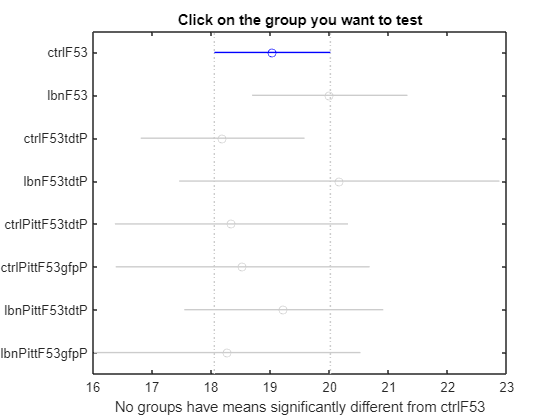

T =     1.0000    2.0000   -3.0908   -0.9722    1.1465    0.8619
    1.0000    3.0000   -1.3814    0.8416    3.0646    0.9462
    1.0000    4.0000   -4.9738   -1.1329    2.7080    0.9867
    1.0000    5.0000   -2.2992    0.6918    3.6828    0.9970
    1.0000    6.0000   -2.6976    0.5018    3.7012    0.9998
    1.0000    7.0000   -2.8207   -0.1922    2.4363    1.0000
    1.0000    8.0000   -2.5626    0.7627    4.0880    0.9971
    2.0000    3.0000   -0.8361    1.8138    4.4636    0.4315
    2.0000    4.0000   -4.2635   -0.1607    3.9420    1.0000
    2.0000    5.0000   -1.6566    1.6640    4.9846    0.7976


 
T = multcompare(STATS)

..........................................................................................................

### 5.4 Relationship between two variables

1. Indicate the data point type and select two variables (X and Y):

statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);
statistic   = statisticList(4);
variableX   = varListInclAge(2);
variableY   = varListInclAge(12);
 

% Check if user inputs are valid
if ~exist('groupedData','var'),fprintf('''groupedData'' not found!');return, end
if ismember('dataPoints',groupedData.Properties.VariableNames)
    if ~ismember(statistic,statisticDone)
        fprintf('Data points for the selected statistic have not been computed yet!\n');return
    end
else
    fprintf('Data points have not been computed yet!\n');return
end

% Ask user to select groups
selectedGroup = selectGroups(groupedData,0)

selectedGroup = 2×1 cell array
    {'ctrlBrownF17tdtN'}
    {'ctrlBrownF17tdtP'}


2. Select a test to run:

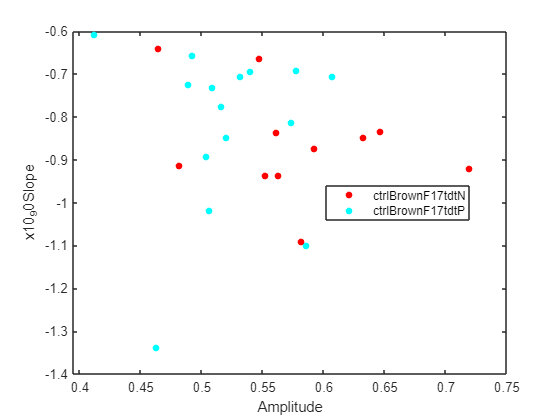

test          = "scatter"; 

% Extract data points and run statistic test

inputX = [];
inputY = [];
groupName = [];
count = 0;

nGroup = length(selectedGroup);
for iGroup = 1:nGroup
    currGroup = selectedGroup{iGroup};
    if variableX == "age"
        inputX = [inputX;groupedData.dataPoints{currGroup}.Amplitude{statistic}.age];        
    else
        inputX = [inputX;groupedData.dataPoints{currGroup}.(variableX){statistic}.dataPoints];
    end
    if variableY == "age"
        inputY = [inputY;groupedData.dataPoints{currGroup}.Amplitude{statistic}.age];
    else
        inputY = [inputY;groupedData.dataPoints{currGroup}.(variableY){statistic}.dataPoints];
    end
    
    nDataPoint = height(groupedData.dataPoints{currGroup}.Amplitude{statistic});
    for iDataPoint = 1:nDataPoint
        groupName{iDataPoint+count,1} = currGroup;
    end
    count = height(groupName);
end

switch test
    case 'scatter', gscatter(inputX,inputY,groupName,'','','','on',variableX,variableY)
    case 'scatterHistogram', scatterhistogram(inputX,inputY,'GroupData',groupName,'HistogramDisplayStyle','smooth')
end

`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# 6. Fit data to exponential or gamma model

**After** you have defined the experiment groups, you can perform the following steps.

..........................................................................................................

### 6.1 Fit each recording to a model (no bootstrapping)

(Same as what `run_ieifit.m` and `run_gammafit.m `do.)

1. Select group(s)

 
% Ask user to select group(s)
fitThese = selectGroups(groupedData,0)

fitThese = 2×1 cell array
    {'chCtrlF78u'}
    {'chLbnF78u' }


2. Fit **IEI** data to exponential model

 
if ~exist("fitThese","var") || isempty(fitThese)
    fprintf('Please select at least a group first.');return;end

% Fit IEI data to exponential model
fprintf('Fitting data...\n');

Fitting data...


nGroup = length(fitThese);
for iGroup = 1:nGroup
    % not running the function directly but turn it into a string and
    % run it with evalc (see below)
    code = "fitEachRecExp(groupedData,'" + fitThese(iGroup) + "')";
    % assign results to a var so that they are not shown in live script
    temp = evalc(code);
    clearvars temp;
end

fprintf(['Done! Each recording was fitted to an exponential model. The output files are:\n' ...
    '- figures containing plots of the fitted data for each recording;\n' ...
    '- ieistats_all.mat containing allparams, allgof, allfiles (file names\n' ...
    '  of recordings) for the group.\n' ...
    'The above files were saved in ../analysis/exponFitting/<group name>/\n' ...
    'Notes:\n' ...
    'allparams: parameters of exponential model\n' ...
    '           (column 1-3: freq, freq CI, number of analyzed events)\n' ...
    '           freq unit is Hz; it is 1000*lambda of CDF;\n' ...
    '           lamda is same as reciprocal of IEI, whose unit is ms.\n' ...
    'allgof: goodness-of-fit results obtained by comparing data to\n' ...
    '        exponential model with MATLAB function kstest2\n' ...
    '        (column 1-3: null hypothesis decision, p value, KS statistic)\n' ...
    'More info: see fitEachRecExp.m']);

Done! Each recording was fitted to an exponential model. The output files are:
- figures containing plots of the fitted data for each recording;
- ieistats_all.mat containing allparams, allgof, allfiles (file names
  of recordings) for the group.
The above files were saved in ../analysis/exponFitting/<group name>/
Notes:
allparams: parameters of exponential model
           (column 1-3: freq, freq CI, number of analyzed events)
           freq unit is Hz; it is 1000*lambda of CDF;
           lamda is same as reciprocal of IEI, whose unit is ms.
allgof: goodness-of-fit results obtained by comparing data to
        exponential model with MATLAB function kstest2
        (column 1-3: null hypothesis decision, p value, KS statistic)
More info: see fitEachRecExp.m

3. Fit **amplitude** data to left-truncated gamma model

 
if ~exist("fitThese","var") || isempty(fitThese)
    fprintf('Please select at least a group first.');return;end

% Fit IEI data to exponential model
fprintf('Fitting data...\n');

Fitting data...


nGroup = length(fitThese);
for iGroup = 1:nGroup
    % not running the function directly but turn it into a string and
    % run it with evalc (see below)
    code = "fitEachRecGamma(groupedData,'" + fitThese(iGroup) + "')";
    % catch results with a var so that they are not shown in live script
    temp = evalc(code);
    clearvars temp;
end

fprintf(['Done! Each recording was fitted to a left-truncated gamma model. The output files are:\n' ...
    '- figures containing plots of the fitted data for each recording;\n' ...
    '- gammastats_all.mat containing allparams, allgof, allfiles (file names\n' ...
    '  of recordings) for the group.\n' ...
    'The above files were saved in ../analysis/gammaFitting/<group name>/\n' ...
    'Notes:\n' ...
    'allparams: parameters of gamma model\n' ...
    '           (column 1-6: alpha, alpha CI, beta, beta CI, mean, mean CI)\n' ...
    'allgof: goodness-of-fit results obtained by comparing data to\n' ...
    '        gamma model with MATLAB function kstest2\n' ...
    '        (column 1-3: null hypothesis decision, p value, KS statistic)\n' ...
    'More info: see fitEachRecGamma.m']);

Done! Each recording was fitted to a left-truncated gamma model. The output files are:
- figures containing plots of the fitted data for each recording;
- gammastats_all.mat containing allparams, allgof, allfiles (file names
  of recordings) for the group.
The above files were saved in ../analysis/gammaFitting/<group name>/
Notes:
allparams: parameters of gamma model
           (column 1-6: alpha, alpha CI, beta, beta CI, mean, mean CI)
allgof: goodness-of-fit results obtained by comparing data to
        gamma model with MATLAB function kstest2
        (column 1-3: null hypothesis decision, p value, KS statistic)
More info: see fitEachRecGamma.m

Optional: You can run the above functions as a script using the codes below.

 

if ~exist("fitThese","var") || isempty(fitThese)
    fprintf('Please select at least a group first.');return;end

% Concatenate all group names into one string
groups = "";
nGroup = length(fitThese);
for iGroup = 1:nGroup
    groups = groups + "'" + string(fitThese(iGroup)) + "' ";
end

% Generate the code for fitting IEI data
code1 = ['fitThese = {' char(groups) '};' newline... 
'nGroup = length(fitThese);' newline ...
'for iGroup = 1:nGroup' newline ...
'    fitEachRecExp(groupedData,fitThese(iGroup));' newline ...
'end'];

% Generate the code for fitting amplitude data
code2 = ['fitThese = {' char(groups) '};' newline... 
'nGroup = length(fitThese);' newline ...
'for iGroup = 1:nGroup' newline ...
'    fitEachRecGamma(groupedData,fitThese(iGroup));' newline ...
'end'];

% Display instructions
fprintf(['- Click to copy the code for fitting IEI data\n' ...
    '- Click to copy the code for fitting amplitude data\n' ...
    '\nIf you are running it in a new MATLAB session, remember to set \n' ...
    'folder paths as instructed in ''analyzeMini.mlx''.\n']);

..........................................................................................................

### 6.2 Run bootstrap on each group and fit to a model

(Same as what `bootstrap_ieigroup.m` and `bootstrap_gammagroup.m` do.)

1. Bootstrap** IEI **data and fit to exponential CDF

 

% Ask user to select group(s)
[bootstrapThese,check] = selectGroups(groupedData,0);
if check == 0, return;end

% Bootstrapping
nGroup = length(bootstrapThese);
for iGroup = 1:nGroup
    bootstrapExp(groupedData,bootstrapThese(iGroup));
end

2. Bootstrap** amplitude **data and fit to left-truncated gamma CDF

 

% Ask user to select group(s)
[bootstrapThese,check] = selectGroups(groupedData,0);
if check == 0, return;end

fprintf(['NOTE: Fitting gamma CDF can be very slow if you run it here.\n' ...
'Alternatively, you can run it in the command window (see optional steps below).\n' ...
'If you have a slow computer, it may be faster to run on MATLAB Online.\n' ...
'For your reference: On Dell XPS13 (2016), it takes ~65s to fit one recording;\n' ...
'~45s if run in command window; ~22s in command window on MATLAB Online.\n\n']);

% Bootstrapping
nGroup = length(bootstrapThese);
for iGroup = 1:nGroup
    bootstrapGamma(groupedData,bootstrapThese(iGroup));
end

3. Plot CDF for bootstrap IEI data

- Select '`Create new figure`' to plot CDF for the first group. To add more groups on the same figure: 

- Keep the current figure window active. Don't activate other figure windows.

- Select '`Plot on current figure`' and repeat this step for each of the subsequent groups.

newFig = 0; 

% Ask user to select a group
[plotThis,check] = selectGroups(groupedData,1);
if check == 0, return;end

% Ask user to select a color
rgbColor = uisetcolor;

% Plot CDF (The plot function is wrapped in evalc so that
% figure will not be displayed in live script output)
temp = evalc('plotBootstrapData_exp(plotThis,newFig,rgbColor)');
clearvars temp;
fprintf('Done! To continue plotting on current figure:\nkeep the figure window active and select ''Plot on current figure''.\n');

4. Plot CDF for bootstrap amplitude data (see instruction in step 3)

newFig = 1; 

% Ask user to select a group
[plotThis,check] = selectGroups(groupedData,1);
if check == 0, return;end

% Ask user to select a color
rgbColor = uisetcolor;

% Plot CDF (The plot function is wrapped in evalc so that
% figure will not be displayed in live script output)
temp = evalc('plotBootstrapData_gamma(plotThis,newFig,rgbColor)');
clearvars temp;
fprintf('Done! To continue plotting on current figure:\nkeep the figure window active and select ''Plot on current figure''.\n');

Optional step 1: You can run bootstrap in the command window or as a script using the codes below. 

 

% Ask user to select group(s)
[bootstrapThese,check] = selectGroups(groupedData,0);
if check == 0,return;end

% Concatenate all group names into one string
groups = "";
nGroup = length(bootstrapThese);
for iGroup = 1:nGroup
    groups = groups + "'" + string(bootstrapThese(iGroup)) + "' ";
end

% Generate the code for fitting IEI data
code1 = ['bootstrapThese = {' char(groups) '};' newline... 
'nGroup = length(bootstrapThese);' newline ...
'for iGroup = 1:nGroup' newline ...
'    bootstrapExp(groupedData,bootstrapThese(iGroup));' newline ...
'end'];

% Generate the code for fitting amplitude data
code2 = ['bootstrapThese = {' char(groups) '};' newline... 
'nGroup = length(bootstrapThese);' newline ...
'for iGroup = 1:nGroup' newline ...
'    bootstrapGamma(groupedData,bootstrapThese(iGroup));' newline ...
'end'];

% Display instructions
fprintf(['- Click to copy the code for boostrapping and fitting IEI data\n' ...
    '- Click to copy the code for boostrapping and fitting amplitude data\n' ...
    '\nIf you are running it in a new MATLAB session, remember to set \n' ...
    'folder paths as instructed in ''analyzeMini.mlx''.\n']);

- Click to copy the code for boostrapping and fitting IEI data
- Click to copy the code for boostrapping and fitting amplitude data

If you are running it in a new MATLAB session, remember to set 
folder paths as instructed in 'analyzeMini.mlx'.


Optional step 2: You can run the plotting functions in the command window or as a script using the code below.

 

% Ask user to select a group
[plotThis,check] = selectGroups(groupedData,1);
if check == 0,return;end

% Generate the codes for plotting
code1 = "plotBootstrapData_exp('"+plotThis+"',newFig,rgbColor);";
code2 = "plotBootstrapData_gamma('"+plotThis+"',newFig,rgbColor);";

% Display instructions
fprintf(['For IEI data: %s\nClick here to copy code\n' ...
    'For Amplitude data: %s\nClick here to copy code\n' ...
    '\nInstructions\n' ...
    '- newFig: Set to 1 to create a new figure; 0 to plot on current figure.*\n' ...
    '- rgbColor: RGB color code of the CDF plot, e.g. set to [0 0 0] for black.\n' ...
    '- If you are running it in a new MATLAB session, remember to set \n' ...
    '  folder paths as instructed in ''analyzeMini.mlx''.\n' ...
    '\n------\n*To plot subsequent groups on the same figure, ' ...
    'keep current figure window open.\n' ...
    'Set newFig to 0 and run the code for each group.\n' ...
    'To set figure size, create a new figure of desired size (see MATLAB documentation) ' ...
    '\nfirst and then run the code with newFig set to 0.'],code1,code2);

..........................................................................................................

### 6.3 Plotting figures with Gramm Toolbox

More info: [https://github.com/piermorel/gramm](https://github.com/piermorel/gramm)

cheat sheet: [https://github.com/piermorel/gramm/raw/master/gramm%20cheat%20sheet.pdf](https://github.com/piermorel/gramm/raw/master/gramm%20cheat%20sheet.pdf)

Cite as: Morel, Pierre. “Gramm: Grammar of Graphics Plotting in Matlab.” The Journal of Open Source Software, vol. 3, no. 23, The Open Journal, Mar. 2018, p. 568, doi:10.21105/joss.00568.

**Export data for plotting:**

statisticDone = string(groupedData.dataPoints{1}.Properties.RowNames);
statistic  = statisticList(1);
variable   = varListInclFreq(1); 

% Check if user inputs are valid
if ~exist('groupedData','var'),fprintf('''groupedData'' not found!');return, end
if ismember('dataPoints',groupedData.Properties.VariableNames)
    if ~ismember(statistic,statisticDone)
        fprintf('Data points for the selected statistic have not been computed yet!\n');return
    end
else 
    fprintf('Data points have not been computed yet!\n');return
end

% Ask user to select groups
selectedGroup = selectGroups(groupedData,0)


selectedGroup =

  0×0 empty cell array



nGroup = length(selectedGroup);

% Generate a list of factors
factorList = string(groupedData.Properties.VariableNames);
% Remove these elements from the list
factorList(factorList=="dataPoints" | factorList=="events" | factorList=="minAge" | factorList=="maxAge") = [];    
% Add group, age group and mouseID to the list
factorList = ["group",factorList,"ageGroup","mouseID"];

% Ask user to select factor(s)
[index,tf] = listdlg('PromptString',...
    {'Select grouping tag(s) to be exported.', ...
    'Press and hold ''Ctrl'' key to select multiple factors.',''},...
    'ListSize',[250,300],'ListString',factorList,'InitialValue',1);
selectedFactor = factorList(index);
nFactor = length(selectedFactor);

% Extract data points and copy the info to a struct called 'input'

input = struct;
input.data = [];    % Create a struct field for data points
for iFactor = 1:nFactor, input.(selectedFactor(iFactor)) = []; end   % create a struct field for each factor
count = 0;

for iGroup = 1:nGroup
    currGroup = selectedGroup{iGroup};
    % Concatenate all recordings into one-column array (input.data):
    input.data = ...
        [input.data;groupedData.dataPoints{currGroup}.(variable){statistic}.dataPoints];
    % Concatenate factor values of all recordings into corresponding 
    % arrays (input.sex, input.ageGroup, etc.):
    for iFactor = 1:nFactor
        currFactor = selectedFactor(iFactor);
        % Concatenate factor values for 'group':
        if currFactor == "group"
            nRecording = length(groupedData.dataPoints{currGroup}.(variable){statistic}.dataPoints);
            for iRecording = 1:nRecording
                input.(currFactor){iRecording+count,1} = currGroup;
            end
            count = count + nRecording;
        % Concatenate factor values for other factors:
        else
            input.(currFactor) = ...
                [input.(currFactor);string(groupedData.dataPoints{currGroup}.(variable){statistic}.(currFactor))];
        end
    end
end

fprintf('Your selected data is exported to a struct array named ''input'' in the Workspace.\n');

Your selected data is exported to a struct array named 'input' in the Workspace.


`                (`[`Table of Contents`](about:blank<#M_2C38E8F0>)`)`

# ----------------------------------------------------

# Maintenance

### Update default values

 
% Default values are case-sensitive.
sampleTypeList = ["recording" "animal" "eventofG" "eventofA" "eventOfR"];
varList = ["Amplitude","Rise_ms_","Decay_ms_","Area","Baseline","Noise","x10_90Rise","HalfWidth","Rise50","x10_90Slope","iei"];
varListInclFreq = ["Amplitude","freq","Rise_ms_","Decay_ms_","Area","Baseline","Noise","x10_90Rise","HalfWidth","Rise50","x10_90Slope","iei"];
varListInclAge = ["age","Amplitude","freq","Rise_ms_","Decay_ms_","Area","Baseline","Noise","x10_90Rise","HalfWidth","Rise50","x10_90Slope","iei"];
statisticList = ["mean" "median" "sd" "cv" "sem"];
save(scriptFolder+'/defaultValues.mat','sampleTypeList','varList','varListInclFreq','varListInclAge','statisticList');
fprintf('Default values updated!')

Default values updated!

source code structure 

dependencies

data structure

adding new functions

variable naming

testing

problem shooting

change log

NOTE: Nesting relationship should be indicated by using an n-by-n matrix, where n is the number of factors and each row/column represent a factor. Example: 3-by-3 matrix, M, for three factors (A, B, C):